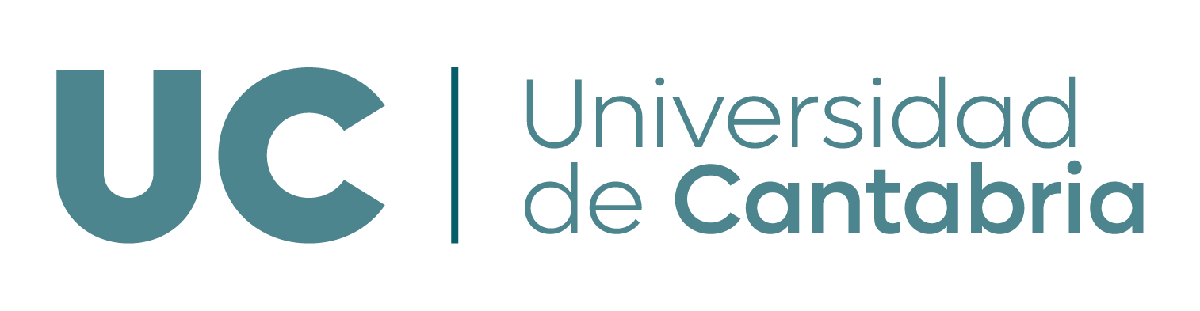

***Grado en Ingeniería en Tecnologías Industriales***

**G414: Álgebra y Geometría**

# **Guion MATLAB: Espacio euclídeo y ortogonalidad**

*Sara Pérez Carabaza (sara.perezcarabaza@unican.es)*

*Valvanuz Fernández Quiruelas (valvanuz.fernandez@unican.es). *

**Objetivos**

- Operar con productos escalares en MATLAB

- Obtener el complemento ortogonal de un subespacio dado

- Obtener bases ortogonales (y ortonormales)

**Funciones de MATLAB utilizadas en este guion: **`dot, norm ,acosd , null, orth`

## **1. Producto escalar, norma y ángulo**

### Producto escalar

En MATLAB, el producto escalar de dos vectores e $\mathbb{R}^n$ se puede obtener multiplicando matricialmente un vector fila por un vector columna. 

Por ejemplo, en $\mathbb{R}^3$, el producto escalar de los vectores $\vec{u}=(4,0,3)$ y $\vec{v}=(1,-2,3)$ se obtendría así:

u = [4 0 3]'; % vector u
v = [1 -2 3]';  % vector v
u'*v

ans = 13

Otra opción muy conveniente es usar la función *dot* de MATLAB. En este caso no hay problema que pasemos los vectores en formato fila o columna, `dot` devolverá su producto escalar.

- `dot(u,v):` producto escalar de dos vectores  

dot(u, v)  % producto escalar usual 

ans = 13

### Norma

La norma de un vector $\|\vec{u} \parallel =\sqrt{\vec{u} \cdot \vec{u} }$ puede calcularse fácilmente con la función *norm. *La función *norm* de MATLAB considera el producto escalar usual, donde la norma coincide con la longitud del vector y es igual a:


$$\|\vec{v}\| = \sqrt{\vec{v} \cdot \vec{v}} = \sqrt{(v_1, v_2, \dots, v_n) \cdot (v_1, v_2, \dots, v_n)} = \sqrt{v_1^2 + v_2^2 + \cdots + v_n^2}
$$


Si estuviésemos trabajando con otro tipo de producto escalar, habría que calcularla "a mano".

- función` norm`*: *devuelve norma de un vector considerando el producto escalar usual

norm(u)  % norma del vector u (considerando el producto escalar usual)

ans = 5

sqrt(dot(u, u))  % comprobamos que obtenemos el mismo resultado

ans = 5

sqrt(u(1)^2+u(2)^2+u(3)^2)  % comprobamos que obtenemos el mismo resultado

ans = 5

**Normalizar** el vector$\vec{u}$ sería tan fácil como:

u_norm = u/norm(u)  % vector normalizado

u_norm =     0.8000
         0
    0.6000


norm(u_norm)  % comprobamos que efectivamente, el módulo del vector normalizado es 1

ans = 1

### **Distancia y ángulo entre dos vectores**

**Distancia entre dos vectores. **La distancia entre dos vectores cualesquiera de un espacio vectorial euclídeo $\vec{u}$y $\vec{v}$, es la norma del vector diferencia entre ambos. Por tanto, la distancia entre dos vectores en Matlab se calcula de la siguiente forma:

v_diff= u-v % vector diferencia u-v 

v_diff =      3
     2
     0


distancia=norm(v_diff) % norma del vector diferencia

distancia = 3.6056

**Ángulo entre dos vectores.** Sabemos que: $$\vec{u} \cdot \vec{v} = \|\vec{u} \| \|\vec{v} \| \cos(\alpha)$, con $0 \leq \alpha \leq \pi$ $. 

Por tanto, el $$\alpha = arccos \frac{\vec{u} \cdot \vec{v}}{ \|\vec{u} \| \| \vec{v} \|}  $$. En Matlab el ángulo (en radianes) se obtendría con la función `acos`, que es la función arccoseno):

alpha=acos(dot(u,v)/(norm(u)*norm(v)))%rad

alpha = 0.8025

La funcion `acosd` nos devuelve el ángulo en radianes

alpha*180/pi %paso a grados

ans = 45.9824

alpha=acosd(dot(u,v)/(norm(u)*norm(v)))%grados

alpha = 45.9824

## **2. Cálculo del subespacio complemeto ortogonal**

Sea $S$ un subespacio de $\mathbb{R}^4$ dado en su forma paramétrica, $S = \lbrace (\alpha, \alpha, \beta, \beta)| \alpha, \beta \in \mathbb{R}\rbrace$. Para encontrar el complemento ortogonal de $S$, denotado $S^
\perp$, tendremos que buscar todos los vectores ortogonales a $S$. Partiremos, para ello, de una base de $S$:

baseS = [1 1 0 0; 0 0 1 1]'  % base de S

baseS =      1     0
     1     0
     0     1
     0     1


$S^\perp$ estará formado por los vectores $(x,y,z,t)$ que satisfagan las siguientes ecuaciones:


$$(1,1,0,0) \cdot (x,y,z,t)=0 \\ (0,0,1,1) \cdot (x,y,z,t)=0$$


Si consideramos el producto escalar usual, esto se puede escribir en forma matricial como:


$$\left\lbrack \begin{array}{cccc}
1 & 1 & 0 & 0\\
0 & 0 & 1 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z\\
t
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$$


Por tanto, para hallar una base de $S^\perp$ bastaría con resolver el sistema homogéneo que tiene como matriz de coeficientes los vectores de la base de $S$ (colocados por filas):

baseS_ortog = null(baseS', 'r')  % base de S_ortog: 

baseS_ortog =     -1     0
     1     0
     0    -1
     0     1


Como vemos, la base de $S^\perp$ está compuesta por dos vectores, por lo que $dim(S^\perp)=2$. Esto era de esperar, puesto que ya vimos que $dim(S)=2$, y sabemos que, por ser subespacios suplementarios.

Comprobemos entonces que  $dim(S)+dim(S^\perp)=4$. Efectivamente:

rank([baseS baseS_ortog])  % la unión de la base de S  y la base de S_ortog forman una base del espacio total, R4

ans = 4

Podemos comprobar fácilmente que $S$ y $S^\perp$ son en efecto ortogonales viendo que el producto escalar de los vectores de sus bases (las combinaciones de todos con todos) es $0$:

% Comprobación ORTOGONALIDAD
dot(baseS(:,1), baseS_ortog(:,1))

ans = 0

dot(baseS(:,1), baseS_ortog(:,2))

ans = 0

dot(baseS(:,2), baseS_ortog(:,1))

ans = 0

dot(baseS(:,2), baseS_ortog(:,2))

ans = 0

## **3. Cálculo de bases ortogonales (y ortonormales)**

Una base ortogonal de un subespacio es aquella formada por un conjunto de vectores ortogonales. Al igual que existen infinitas bases de un subespacio, también existen infinitas bases ortogonales de un subespacio. 

Para obtener una base ortogonal tenemos tres opciones que veremos a continuación:

- La función `orth de MATLAB`

- El método de ortogonalización de Gram-Smichdt

- El uso de la función `null.`

### 3.1 Función orth: Ortonormalización de un conjunto de vectores

En clase hemos visto el algoritmo de Gram-Schmidt para ortogonalizar una base. MATLAB permite ortogonalizar una base mediante el uso de la función `orth`

- `orth`(A): esta función toma como argumento de entrada una matriz$A$ y devuelve una matriz cuyos vectores columna forman una base ortonormal del espacio generado por los vectores columna de $A$. Es decir devolverá una matriz con una base en sus columnas (tantas columnas como la dimensión del espacio columna de $A$). Es importante tener en cuenta que la base ortonormal devuelta por `orth` no es la misma que obtendríamos por Gram-Schmidt, sino que implementa un procedimiento de ortonormalización diferente. Recuerda que existen infinitas bases ortonormales de un subespacio.

**Ejemplo**. Dado el siguiente subespacio,$$S=\{(x,y,z) \in  \mathbb{R}^3: 2x-y+3z=0 \}$
$ vamos a obtener una base ortonormal de $S$ utilizando la funcion de matlab `orth`.

Para empezar necesitamos una base cualquiera de S, para hallarla pasamos de implícitas a paramétricas resolviendo el sistema.

coefS=[ 2 -1 0];
%vectores de la base de S en columnas
baseS=null(coefS,"rational")%base no ortogonal de S

baseS =     0.5000         0
    1.0000         0
         0    1.0000


   Ya tenemos la base (no ortogonal) de $S$. Ahora utilizaremos la función `orth` para ortonormalizar la base.


$$$  \left(x, y, z\right)=\left(\alpha/2 - \frac{3}{2}\beta, \alpha, \beta \right)=\alpha (\frac{1}{2},1,0)+ \beta(-\frac{3}{2},0,1)$
$$


base_ort=orth(baseS)

base_ort =    -0.4472         0
   -0.8944         0
         0   -1.0000


Comprobamos que hemos obtenido una base ortonormal

dot(base_ort(:,1),base_ort(:,2))%base ortogonal

ans = 0

[norm(base_ort(:,1))  norm(base_ort(:,2)) ]%base ortonormal (vectores unitarios)

ans =     1.0000    1.0000


Comprobamos además que los vectores de la base de $S$ satisfacen la ecuación implícita de $S$

coefS*base_ort(:,1)% el primer vector de la base verifica la ecuacion implícita de S (A*v1=0)

ans = 0

coefS*base_ort(:,2)% el segundo vector de la base  verifica la ecuacion implícita de S (A*v2=0)

ans = 0

### 3.2. Gram-Schmidt: Ortonormalización de un conjunto de vectores

Aunque MATLAB no tenga implementada una función con el algoritmo de Gram-Schmidt podemos implementar el algoritmo de vectores "a mano". Veamos un ejemplo. 

Dado el siguiente subespacio, vamos a implementar el algoritmo de Gram-Schmidt para obtener una base ortonormal de $S$.

   $$  \left(x, y, z\right)=\left(\alpha/2 - \frac{3}{2}\beta, \alpha, \beta \right)=\alpha (\frac{1}{2},1,0)+ \beta(-\frac{3}{2},0,1)$
$, 

v1=[1/2 1 0]';
v2=[-3/2 0 1]';

Implementamos el algoritmo de Gram-Schmidt para obtener una base ortogonal:


$$ \vec{u}_{1}=\vec{v}_{1}=(\frac{1}{2},1,0) 
$$



$$ \vec{u}_{2}=\vec{v}_{2} - proy_{\vec{u}_{1}}(\vec{v}_{2})= 
\vec{v}_{2} - \displaystyle \Big(\frac{\vec{v}_{2} \cdot \vec{u}_{1}}{\vec{u}_{1} \cdot \vec{u}_{1}}\Big) \vec{u}_{1} $$


%Gram-Schmidt (conjunto de 2 vectores)
u1=v1;
u2=v2-dot(v2,u1)/dot(u1,u1)*u1

u2 =    -1.2000
    0.6000
    1.0000


Ya tenemos una base ortogonal, para obtener una base ortonormal normalizamos los vectores

u1=u1/norm(v1)

u1 =     0.4472
    0.8944
         0


u2=u2/norm(v2)

u2 =    -0.6656
    0.3328
    0.5547


**Comprobación **de que la base obtenida del subepacio $S$ es ortogonal:

dot(u1,u2)%producto escalar nulo -> v1 ortogonal a v2

ans = 0

### 3.3 null: hallar una base ortonormal a partir de ecuaciones implícitas

- null(A): la función null de A devuelve una base de un sistema homogéneo cuya matriz de coeficientes es A. Si no ponemos el argumento "r" o "rational"  nos devolverá una base ortonormal.

- null(A,"r"): Si  ponemos el argumento "r" o "rational"  nos devolverá una base no  ortogonal con vectores con número enteros o numero racionales.

 Por ejemplo, para el subespacio $$S=\{(x,y,z) \in  \mathbb{R}^3: 2x-y+3z=0 \}$
$

Si indicamos el argumento 'rational' nos devolverá una base con números racionales, pero que no tiene porque ser ortogonal.

coefImpS = [2 -1 2];  % coefs. eqs. implícitas S
baseS = null(coefImpS, 'rational')  % base de S (no ortogonal)

baseS =     0.5000   -1.0000
    1.0000         0
         0    1.0000


dot(baseS(:,1), baseS(:,2))  % vemos que NO es ortogonal -> no es ortonormal

ans = -0.5000

Si no añadimos el argumento '`rational`', la función `orth` devuelve una base ortonormal.

baseortonS = null(coefImpS)  % base ORTONORMAL de S

baseortonS =     0.3333   -0.6667
    0.9333    0.1333
    0.1333    0.7333


% comprobación de ortonorgonalidad
dot(baseortonS(:,1), baseortonS(:,2))

ans = 0

% Comprobación ORTONORMALIDAD 
[ norm(baseortonS(:,1)) norm(baseortonS(:,2)) ]

ans =      1     1


`Nota``:` fíjate que las base ortogonales obtenidas para el subespaico $$S=\{(x,y,z) \in  \mathbb{R}^3: 2x-y+3z=0 \}$
$ por las funciones `orth` , `null` y el método GS son diferentes.

## Bibliografía 

- Guiones para Matlab realizados por Rodrigo García Manzanas y Ruth Carballo Fidalgo para la asignatura de Álgebra y Geometría del Grado en Ingeniería Civil.